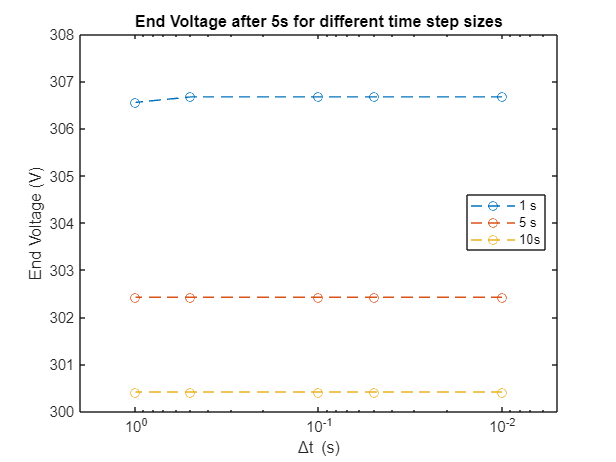

load("fmu_tran_1s.mat");
load("fmu_tran_001s.mat");
load("fmu_tran_005s.mat"); 

%voltage for 0.01-1s tss and for 1,5,10s
voltage_tran = [306.66791088542357 , 306.66791088542357 , 306.66791088542357 , 306.66791088542357 , 306.5519556291654
; fmu_tran_001s(5,501) , 302.4189561573149 , 302.4189561573149 , 302.4189561573149 , 302.4189561573149
; fmu_tran_001s(5,1001) , 300.41118676020034 , 300.41118676020034 , 300.41118676020034 , 300.41118676020034];

h2_tran = [0.27927516133367253 , 0.27927516133367253 , 0.27927516133367253 , 0.27927516133367253 , 0.27927516133367253 
; fmu_tran_001s(2,501) , 0.3076766868648583 , 0.307676686864858 , 0.307676686864855 ,0.3076766868648583
; fmu_tran_001s(2,1001) , 0.31497461467551746 , 0.31497461467551746 , 0.31497461467551746 , 0.31497461467551746];

ts2= [0.01 , 0.05 , 0.1 , 0.5 , 1];

semilogx(ts2, voltage_tran, "o--")
xlim([0.005, 2])
ylim([300,308])
set(gca, 'XDir', 'reverse')
legend("1 s" , "5 s" , "10s", "Location" , "east")
xlabel("\Deltat (s)")
ylabel("End Voltage (V)")
title("End Voltage after 5s for different time step sizes")

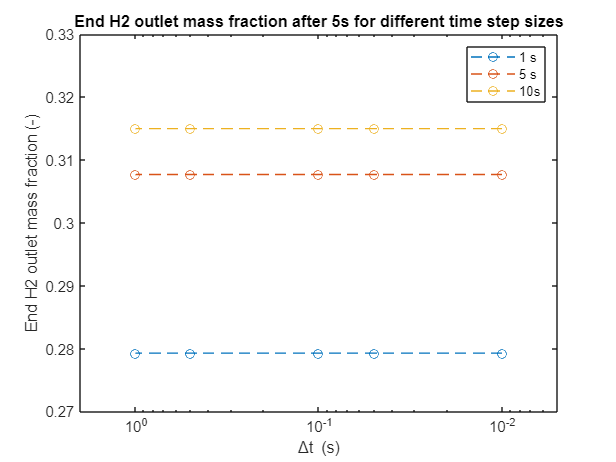



semilogx(ts2, h2_tran, "o--")
xlim([0.005, 2])
ylim([0.27,0.33])
set(gca, 'XDir', 'reverse')
legend("1 s" , "5 s", "10s")
xlabel("\Deltat (s)")
ylabel("End H2 outlet mass fraction (-)")
title("End H2 outlet mass fraction after 5s for different time step sizes")